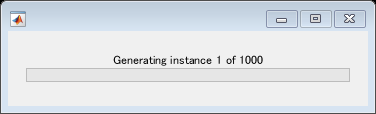

使い方によるエラー save
'data\64beacons_1000instances_free' が存在しないため、'data_instance_1.mat' を作成できません。

% Set the number of instances you want to generate
numInstances = 1000;  % You can adjust as needed
numSimulations = 10;  % Number of measurements per node pair, similar to num_measurements in Python

% Map origin (bottom-left corner)
mapOriginLat = 40.466198;  % Latitude
mapOriginLon = 33.898610;  % Longitude

% Map and tile sizes in meters
mapSizeMeters = 4000;    % 4 km
tileSizeMeters = 1000;    % 2 km
numTilesPerAxis = mapSizeMeters / tileSizeMeters;  % Should be 2

% Earth's radius in meters
earthRadius = 6378137;  % Mean radius

% Conversion factors
metersPerDegreeLat = (pi / 180) * earthRadius;
metersPerDegreeLon = (pi / 180) * earthRadius * cosd(mapOriginLat);

% Degrees per meter
degPerMeterLat = 1 / metersPerDegreeLat;
degPerMeterLon = 1 / metersPerDegreeLon;

% Initialize arrays for anchor positions
numAnchors = numTilesPerAxis^2;  % Total of 4 anchors
anchorLatitudes = zeros(numAnchors, 1);
anchorLongitudes = zeros(numAnchors, 1);

% Place anchors randomly within each tile
anchorIndex = 1;
for i = 0:(numTilesPerAxis - 1)
    for j = 0:(numTilesPerAxis - 1)
        % Tile boundaries in meters
        xMin = i * tileSizeMeters;
        yMin = j * tileSizeMeters;

        % Random position within the tile (in meters from origin)
        xPosMeters = xMin + rand() * tileSizeMeters;
        yPosMeters = yMin + rand() * tileSizeMeters;

        % Convert meters to degrees
        deltaLat = yPosMeters * degPerMeterLat;
        deltaLon = xPosMeters * degPerMeterLon;

        % Anchor position in degrees
        anchorLatitudes(anchorIndex) = mapOriginLat + deltaLat;
        anchorLongitudes(anchorIndex) = mapOriginLon + deltaLon;
        anchorIndex = anchorIndex + 1;
    end
end

% Fixed anchor positions saved for re-use
fixedAnchorLatitudes = anchorLatitudes;
fixedAnchorLongitudes = anchorLongitudes;

% Create a waitbar to show the progress
hWait = waitbar(0, 'Generating dataset, please wait...');

for instanceIdx = 1:numInstances
    % Update the progress in the waitbar
    waitbar(instanceIdx / numInstances, hWait, sprintf('Generating instance %d of %d', instanceIdx, numInstances));

    % Place unknown nodes randomly in the entire area
    numUnknowns = 48;

    % Random positions within the map in meters
    unknownXPosMeters = rand(numUnknowns, 1) * mapSizeMeters;
    unknownYPosMeters = rand(numUnknowns, 1) * mapSizeMeters;

    % Convert meters to degrees
    deltaLatUnknown = unknownYPosMeters * degPerMeterLat;
    deltaLonUnknown = unknownXPosMeters * degPerMeterLon;

    % Unknown node positions in degrees
    unknownLatitudes = mapOriginLat + deltaLatUnknown;
    unknownLongitudes = mapOriginLon + deltaLonUnknown;

    % Combine anchor and unknown positions into a node list
    nodeLatitudes = [fixedAnchorLatitudes; unknownLatitudes];
    nodeLongitudes = [fixedAnchorLongitudes; unknownLongitudes];

    % --- Signal Strength Simulation Setup ---
    % Simulation settings
    frequency = 915e6; % Frequency in Hz
    % prop_model = propagationModel("longley-rice");
    prop_model = propagationModel("freespace");

    % Signal strength matrix initialization for multiple simulations
    totalNodes = numAnchors + numUnknowns;
    signal_strength_matrix = zeros(totalNodes, totalNodes, numSimulations);

    % Iterate through each node to simulate the signal strength between all nodes
    for i = 1:totalNodes
        % Set txsite for the transmitter node
        tx = txsite('Latitude', nodeLatitudes(i), 'Longitude', nodeLongitudes(i), ...
                    'TransmitterFrequency', frequency, 'TransmitterPower', 0.020, 'AntennaHeight', 1.0);

        for j = 1:totalNodes
            if i ~= j
                % Set rxsite for the receiver node
                rx = rxsite('Latitude', nodeLatitudes(j), 'Longitude', nodeLongitudes(j), ...
                            'ReceiverSensitivity', -135, 'AntennaHeight', 1.0);

                % Run multiple simulations to generate multiple signal strength values
                for k = 1:numSimulations
                    % Calculate the signal strength using the propagation model
                    ss = sigstrength(rx, tx, prop_model);  % Use the propagation model directly

                    % Store the signal strength in the matrix
                    signal_strength_matrix(i, j, k) = ss;
                end
            else
                % Set self-transmission to NaN
                signal_strength_matrix(i, j, :) = NaN;
            end
        end
    end

    % Save data to file for each instance
    filename = sprintf('data/64beacons_1000instances_free/data_instance_%d.mat', instanceIdx);
    save(filename, 'nodeLatitudes', 'nodeLongitudes', 'signal_strength_matrix');
end


% Close the waitbar
close(hWait);

% --- Final Visualization to Validate Data ---

% Plot the locations of nodes for the last instance generated
figure;
geoplot(nodeLatitudes, nodeLongitudes, 'bo', 'MarkerSize', 5);
hold on;
geoplot(fixedAnchorLatitudes, fixedAnchorLongitudes, 'g^', 'MarkerSize', 8, 'MarkerFaceColor', 'g');
title(sprintf('Node Locations for Instance %d', numInstances));
legend('Unknown Nodes', 'Anchor Nodes');
hold off;

% Display an example of signal strength between the first node and others
tx_node_index = 1;
signal_strength_values = signal_strength_matrix(tx_node_index, :, 1); % Use the first simulation set for visualization

figure;
geoplot(nodeLatitudes, nodeLongitudes, 'bo', 'MarkerSize', 5);
hold on;
geoplot(fixedAnchorLatitudes, fixedAnchorLongitudes, 'g^', 'MarkerSize', 8, 'MarkerFaceColor', 'g');
geoplot(nodeLatitudes(tx_node_index), nodeLongitudes(tx_node_index), 'rp', 'MarkerSize', 10, 'MarkerFaceColor', 'r');

for i = 1:totalNodes
    if i ~= tx_node_index && ~isnan(signal_strength_values(i))
        % Color intensity based on signal strength value (normalized for visualization)
        signal_strength = signal_strength_values(i);

        % Normalization of signal strength values to range between 0 and 1
        normalized_ss = (signal_strength - min(signal_strength_values(:))) / ...
                        (max(signal_strength_values(:)) - min(signal_strength_values(:)));

        % Interpolation between green (strong signal) and red (weak signal)
        color_intensity = [1, 1 - normalized_ss, 0];  % RGB color from green (strong) to red (weak)

        % Plot line from transmitter to receiver with appropriate color
        geoplot([nodeLatitudes(tx_node_index), nodeLatitudes(i)], ...
                [nodeLongitudes(tx_node_index), nodeLongitudes(i)], ...
                'Color', color_intensity, 'LineWidth', 1.5);
    end
end

title(sprintf('Signal Strength from Transmitter Node %d (Instance %d)', tx_node_index, numInstances));
legend('Unknown Nodes', 'Anchor Nodes', 'Transmitter Node', 'Signal Strength');
hold off;

% Add a colorbar to represent signal strength values in dBm
colormap(flipud([linspace(0, 1, 256)', linspace(1, 0, 256)', zeros(256, 1)])); % Green to Red gradient
colorbar;
caxis([min(signal_strength_values(:)), max(signal_strength_values(:))]);
ylabel(colorbar, 'Signal Strength (dBm)');



